# Algebra Lineal - Resolucio de sistemes

A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


#### DETERMINANT

det(A)

ans = 114

#### NORMA

A1 = norm(A,1); % per columnes
A2 = norm(A,2);  % Es correspon am el calcul següent: max(sqrt(eig(A * A')))
A3 = norm(A,'inf'); % per files

A1, A2, A3

A1 = 14

A2 = 10.6260

A3 = 12

#### INVERSA

B = inv(A);
test1 = B*A;
test2 = A*B;
B, test1, test2

B =     0.6404   -0.1842   -0.0088
    0.2018    0.0789   -0.0439
   -0.0439    0.0263    0.0965


test1 =     1.0000   -0.0000    0.0000
   -0.0000    1.0000   -0.0000
         0         0    1.0000


test2 =     1.0000    0.0000         0
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


#### VECTORS PROPIS

[V,D] = eig(A), inv(V)*A*V

V =     0.9190   -0.3463    0.2439
    0.3889   -0.9204    0.6734
   -0.0645   -0.1816    0.6978


D =     1.7761         0         0
         0    6.8394         0
         0         0    9.3844


ans =     1.7761   -0.0000    0.0000
   -0.0000    6.8394    0.0000
   -0.0000   -0.0000    9.3844


#### DIVERSES MATRIUS

#### Simples

nula = zeros(5);
one = ones(5);
id = eye(5);
nula, one, id

nula =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


one =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


id =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


#### Aleatorias

randomFloat = rand(5);
randomInt = randi(5);

randomFloat, randomInt

randomFloat =     0.8988    0.4371    0.5254    0.5095    0.0576
    0.2734    0.5400    0.5605    0.8247    0.6829
    0.6463    0.1244    0.3015    0.0875    0.8763
    0.1313    0.3108    0.4829    0.2264    0.3680
    0.7259    0.5195    0.8084    0.7730    0.0302


randomInt = 2

#### Matrius Especials

Hilb = hilb(5);     % Matriz de hilbert
IHilb = invhilb(5); % Inversa de la matriz de hilbert

Magic = magic(5);       % Matriz en la que sus filas y sus columnas suman un valor constante.

Diag = diag( [1 2 3 4 5] );
Tup = triu(Magic);
Tdown = triu(Magic, -1);

Hilb, IHilb, Magic, Diag, Tup, Tdown

Hilb =     1.0000    0.5000    0.3333    0.2500    0.2000
    0.5000    0.3333    0.2500    0.2000    0.1667
    0.3333    0.2500    0.2000    0.1667    0.1429
    0.2500    0.2000    0.1667    0.1429    0.1250
    0.2000    0.1667    0.1429    0.1250    0.1111


IHilb =           25        -300        1050       -1400         630
        -300        4800      -18900       26880      -12600
        1050      -18900       79380     -117600       56700
       -1400       26880     -117600      179200      -88200
         630      -12600       56700      -88200       44100


Magic =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


Diag =      1     0     0     0     0
     0     2     0     0     0
     0     0     3     0     0
     0     0     0     4     0
     0     0     0     0     5


Tup =     17    24     1     8    15
     0     5     7    14    16
     0     0    13    20    22
     0     0     0    21     3
     0     0     0     0     9


Tdown =     17    24     1     8    15
    23     5     7    14    16
     0     6    13    20    22
     0     0    19    21     3
     0     0     0     2     9


Relocuion de sistema

n = 20; m = 20;
A = zeros(n,m);

for j = 1:m
    for i = 1:n
        if i < j
            A(i,j) = j;
        elseif i == j
            A(i,j) =  -1;
        else
            break;
        end
    end
end


B = (2.^(-(1:20)))';

A, B

A =     -1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0    -1     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0    -1     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0    -1     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0     0    -1     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0     0     0    -1     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0     0     0     0    -1     8     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0     0     0     0     0    -1     9    10    11    12    13    14    15    16    17    18    19    20
     0     0     0     0    

B =     0.5000
    0.2500
    0.1250
    0.0625
    0.0313
    0.0156
    0.0078
    0.0039
    0.0020
    0.0010


#### Internamente, se factoriza la matriz en dos triangulares L y U, y se resuelve el sistema:

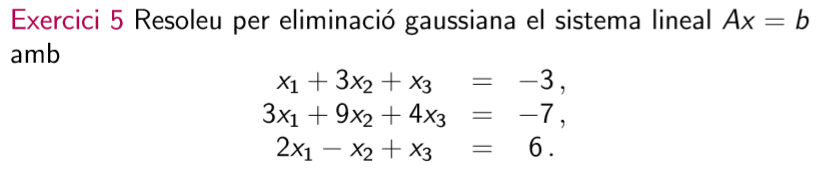

A = [1 3 1; 3 9 4; 2 -1 1];
b = [-3 -7 6]';

% Resolucion MATLAB
x = A\b;

Siulamos la resolucion de Matlab:

[L,U,P] = lu(A);     % Factorizacion en 2 triagulares (lugui(A))
y = L\(P*b);         % 1) Ly = Pb
x = U\y;             % 2) Ux = y

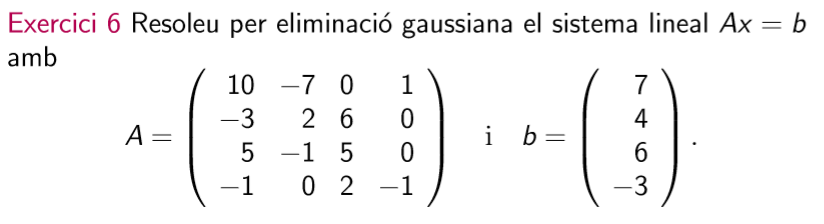

A = [ 10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]; b = [7 4 6 -3]';

% Resolucion MATLAB
x = A\b;

#### Para una matriz simetrica -> Cholesky

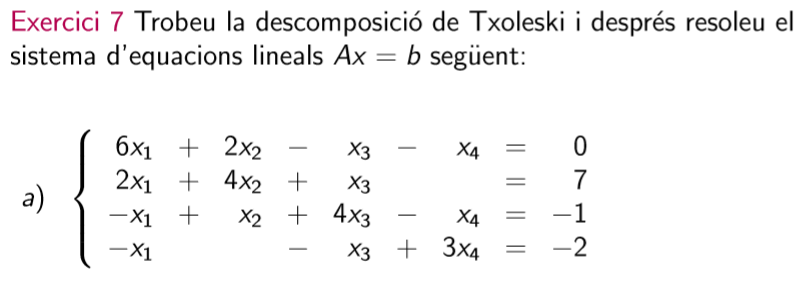

A = [ 6 2 -1 -1;2 4 1 0; -1 1 4 -1; -1 0 -1 3]; b = [0 7 -1 -2]';

isequal(A,A')

ans = logical
   1


R = chol(A);    % Como la matriz es simetrica, se resuelve asi:
y = R'\b;       % 1) R'y = b
x = R\y         % 2) Rx = y

x =    -1.6291
    3.0331
   -1.8742
   -1.8344


#### Resolucion por Factorizacion QR

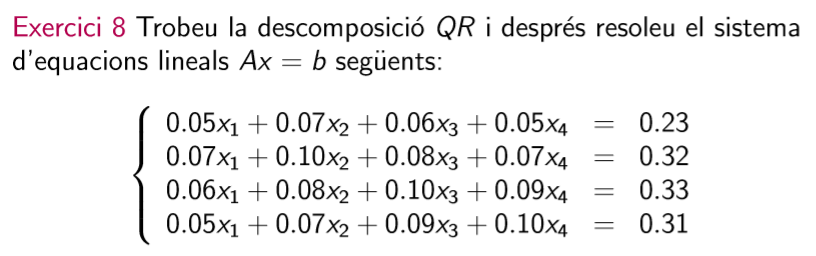

A = [0.05 0.07 0.06 0.05; 0.07 0.10 0.08 0.07; 0.06 0.08 0.10 0.09; 0.05 0.07 0.09 0.10];
b = [0.23 0.32 0.33 0.31]';

[q, r] = qr(A);
x = r\(q' * b);   % 1) rx = q'b
x = backsubs(r,(q'*b)) % lo mismo que antes

x =     1.0000
    1.0000
    1.0000
    1.0000


#### RESIDUS

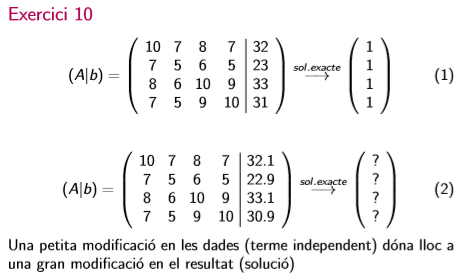

A = [10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10]; b = [32 23 33 31]'; bmod = [32.1 22.9 33.1 30.9]';

x = A\b;
xmod = A\bmod;

% error
r = norm(A*xmod - b, 1);
deltaB = norm(b - bmod, 1);

cond(A), det(A)

ans = 2.9841e+03

ans = 1.0000

x, xmod, r, deltaB

x =     1.0000
    1.0000
    1.0000
    1.0000


xmod =     9.2000
  -12.6000
    4.5000
   -1.1000


r = 0.4000

deltaB = 0.4000

Pequeños cambios en el sistema pueden provocar grandes errores en la solucion. La matriz del sistema tiene una condicion alta (lo cual es malo).